addpath('Classes')
addpath('Simulink Models')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);

# Numerically Finding a Nonlinear Angular Setpoint

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 

%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 

%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params
end

plant_model = rhs(BP_Kinetics.NL_NumEOMs); %Choose the coupled nonlinear model as the plant. Torques still approximated

if (~exist('LMSPC_FF', 'var'))

    LMSPC_FF = Lin_Mvng_Stpt_Cntr_SS(Lnrzed_EOMs, plant_model, VDefs, 'SS PID FF Controller');

end

## Desired Trajectory

Desired Analytical Trajectories in x and y

%Ideal trajectory parameters
r_sim = .15; % radius of trajectory [m] Touch screen is about 30 cm wide

%Rose curve specified by k
tot_period = 5 %this many seconds before the entire rose curve loops around

tot_period = 5

n = 3; %Selects a rose curve
d = 5; %Selects a rose curve
k = n/d; 
omega_sim = omega_rose(tot_period,n,d)

omega_sim = 3.1416

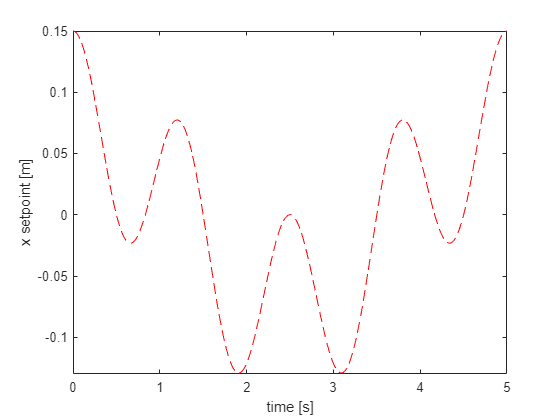

des_traj_sym_x(VDefs.t) = r_sim/2*(cos((k+1)*omega_sim*VDefs.t) + cos((k-1)*omega_sim*VDefs.t));
des_traj_sym_y(VDefs.t) = r_sim/2*(sin((k+1)*omega_sim*VDefs.t) - sin((k-1)*omega_sim*VDefs.t));

figure
fplot(des_traj_sym_x, 'r--') 
xlim([0 tot_period]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

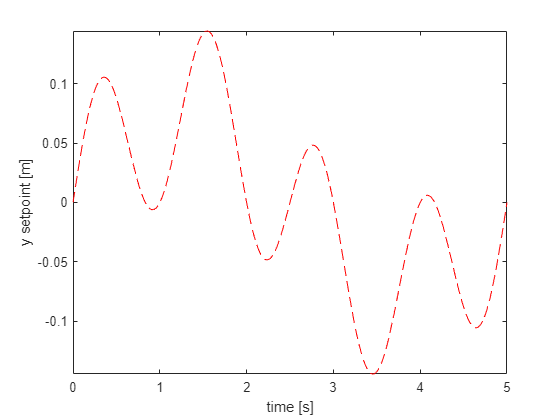


figure
fplot(des_traj_sym_y, 'r--') 
xlim([0 tot_period]); 
ylabel('y setpoint [m]')
xlabel('time [s]')

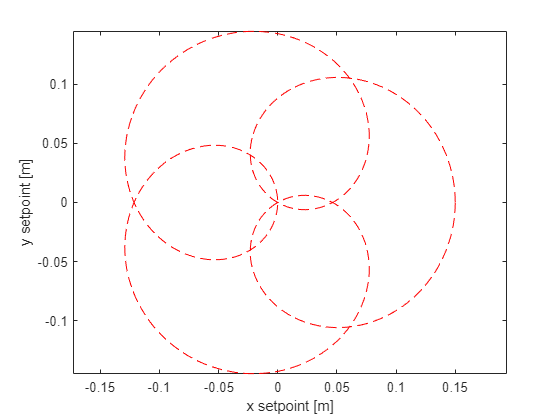


tplot = 0:0.01:tot_period;
setpoint_shape = double([des_traj_sym_x(tplot)',des_traj_sym_y(tplot)']);
figure
plot(setpoint_shape(:,1),setpoint_shape(:,2), 'r--')
xlabel('x setpoint [m]')
ylabel('y setpoint [m]')
axis equal

%Assign to x_s_vec and y_s_vec
x_s_vec = [des_traj_sym_x;diff(des_traj_sym_x)];
y_s_vec = [des_traj_sym_y;diff(des_traj_sym_y)];

## Beta

### Eliminate the Input from the Nonlinear Decoupled EOMs for System 1 and Isolate beta_ddot

beta_ddot_eqn = isolate(0 == eliminate(NL_Dcpld_EOMs.NumDcpldEOMs([2 4]),VDefs.T_beta),VDefs.beta_ddot)
% x_ddot_eqn = isolate(beta_ddot_eqn,VDefs.x_ddot)

### Find the Linear Particular Solution and the Boundary Values

dd_x_s = diff(des_traj_sym_x,2);
syms beta_s(t) C1 C2
%beta 
T_beta_eqn_lin = isolate(VDefs.beta_ddot == Lnrzed_EOMs.Lin_EOMs(4), VDefs.T_beta);
T_beta_eqn_lin = subs(T_beta_eqn_lin,[VDefs.beta, VDefs.beta_ddot],[beta_s, diff(beta_s,2)]);    
ode_beta_s = dd_x_s == subs(Lnrzed_EOMs.Lin_EOMs(2), VDefs.T_beta, rhs(T_beta_eqn_lin));
ode_beta_s = subs(ode_beta_s, VDefs.beta, beta_s); 
%Solve the linear ODE for beta_s(t)
beta_s_sol(VDefs.t) = dsolve(ode_beta_s);
%Take only the particular solution 
beta_s_sol = subs(beta_s_sol, [C1 C2], [0 0])
beta_s_sol_dot(VDefs.t) = diff(beta_s_sol)
BVs = double(beta_s_sol([0 n*d/freq])) %I think 2*n*d/freq gives the period of the rose curve

### Produce a State Space Representation of the Nonliear ODE and Generate an EOM Function Handle 

beta_ddot_fun = matlabFunction(subs(rhs(beta_ddot_eqn), [VDefs.x_ddot, VDefs.x], [dd_x_s,des_traj_sym_x]))
beta_EOM_fun = @(t,x)[x(2)
                      beta_ddot_fun(x(1),x(2),t)]
beta_EOM_fun(0,BVs)

### Formulate the ODE as BVP and try Solving Using a BVP Solver 

Use the linear solution over the interval as an initial guess:

bcfcn_handle = @(ya,yb)bcfcn(ya,yb,BVs); %Residual error in the BCs function
tmesh = linspace(0,tot_period,10000); %Mesh for the initial guess
guess_fun = matlabFunction([beta_s_sol;beta_s_sol_dot]); %Initial guess at y1 and y2 (states) is beta and beta_dot from the linear solution
solinit = bvpinit(tmesh,guess_fun);
beta_BVP_sol = bvp5c(beta_EOM_fun,bcfcn_handle,solinit);
guess_mesh = guess_fun(tmesh);

%Plot the bvp5c solution
figure
subplot(2,1,1)
plot(beta_BVP_sol.x,rad2deg(beta_BVP_sol.y(1,:)),tmesh,rad2deg(guess_mesh(1,:)))
xlabel('time [s]')
ylabel('beta [deg]')
legend('Nonlinear Numerical Solution','Linear Solution')

subplot(2,1,2)
plot(tmesh,rad2deg(beta_BVP_sol.y(1,:))-rad2deg(guess_mesh(1,:)))
xlabel('time [s]')
ylabel('e_{beta} [deg]')

%Make figure larger
set(gcf,'position',[0,0,700,700]);   

### Compare the BVP Solver's Estimate of beta_ddot to the Linear beta_ddot

Compare the error to the error in the linear approximate solution plugged into the ODE

beta_ddot_BVP = beta_ddot_fun(beta_BVP_sol.y(1,:),beta_BVP_sol.y(2,:),tmesh); %BVP solver's guess at beta_ddot
beta_ddot_lin = beta_ddot_fun(guess_mesh(1,:),guess_mesh(2,:),tmesh); %Linear solution's beta_ddot
e_beta_ddot = beta_ddot_BVP - beta_ddot_lin;

figure
plot(tmesh,e_beta_ddot)

### Compute the T_beta Feed-Forward Torque Data and Plot

%Nonlinear feed-forward torque
T_beta_eqn_NL = rhs(isolate(subs(NL_Dcpld_EOMs.NumDcpldEOMs(4),[VDefs.x; VDefs.x_dot],x_s_vec), VDefs.T_beta)); %Symbolic equation for T_beta
T_beta_FF_fun = matlabFunction(T_beta_eqn_NL) %Matlab function generated from the symbolic equation for T_beta
T_beta_FF_data = [beta_BVP_sol.x;T_beta_FF_fun(beta_BVP_sol.y(1,:),beta_BVP_sol.y(2,:),beta_ddot_BVP,beta_BVP_sol.x)]; %FF torque and associated times

%Linear feed-forward torque
T_beta_eqn_lin(VDefs.t) = rhs(subs(T_beta_eqn_lin, [beta_s, VDefs.x], [beta_s_sol,[1 0]*x_s_vec]))

figure 
hold on
plot(T_beta_FF_data(1,:),T_beta_FF_data(2,:))
fplot(T_beta_eqn_lin, [beta_BVP_sol.x(1) beta_BVP_sol.x(end)])
hold off
xlabel('time [s]')
ylabel('T_{beta,FF} [Nm]')
title('Feed-Forward Torque for System 1')
legend('NL FF T_{beta}', 'Lin FF T_{beta}')

## Gamma

### Eliminate the Input from the Nonlinear Decoupled EOMs for System 1 and Isolate beta_ddot

gamma_ddot_eqn = isolate(0 == eliminate(NL_Dcpld_EOMs.NumDcpldEOMs([6 8]),VDefs.T_gamma),VDefs.gamma_ddot)

### Find the Linear Particular Solution and the Boundary Values

dd_y_s = diff(des_traj_sym_y,2);
syms gamma_s(t) C1 C2

T_gamma_eqn_lin = isolate(VDefs.gamma_ddot == Lnrzed_EOMs.Lin_EOMs(8), VDefs.T_gamma);
T_gamma_eqn_lin = subs(T_gamma_eqn_lin,[VDefs.gamma, VDefs.gamma_ddot],[gamma_s, diff(gamma_s,2)]);    
ode_gamma_s = dd_y_s == subs(Lnrzed_EOMs.Lin_EOMs(6), VDefs.T_gamma, rhs(T_gamma_eqn_lin));
ode_gamma_s = subs(ode_gamma_s, VDefs.gamma, gamma_s); 

%Solve the linear ODE for gamma_s(t)
gamma_s_sol(VDefs.t) = dsolve(ode_gamma_s);
%Take only the particular solution 
gamma_s_sol = subs(gamma_s_sol, [C1 C2], [0 0])
gamma_s_sol_dot(VDefs.t) = diff(gamma_s_sol)
BVs = double(gamma_s_sol([0 n*d/freq])) %I think 2*n*d/freq gives the period of the rose curve

### Produce a State Space Representation of the Nonliear ODE and Generate an EOM Function Handle 

gamma_ddot_fun = matlabFunction(subs(rhs(gamma_ddot_eqn), [VDefs.y_ddot, VDefs.y], [dd_y_s,des_traj_sym_y]))
gamma_EOM_fun = @(t,x)[x(2)
                      gamma_ddot_fun(x(1),x(2),t)]
gamma_EOM_fun(0,BVs)

### Formulate the ODE as BVP and try Solving Using a BVP Solver 

Use the linear solution over the interval as an initial guess:

bcfcn_handle = @(ya,yb)bcfcn(ya,yb,BVs); %Residual error in the BCs function
tmesh = linspace(0,tot_period,10000); %Mesh for the initial guess
guess_fun = matlabFunction([gamma_s_sol;gamma_s_sol_dot]); %Initial guess at y1 and y2 (states) is gamma and gamma_dot from the linear solution
solinit = bvpinit(tmesh,guess_fun);
gamma_BVP_sol = bvp5c(gamma_EOM_fun,bcfcn_handle,solinit);
guess_mesh = guess_fun(tmesh);

%Plot the bvp5c solution
figure
subplot(2,1,1)
plot(gamma_BVP_sol.x,rad2deg(gamma_BVP_sol.y(1,:)),tmesh,rad2deg(guess_mesh(1,:)))
xlabel('time [s]')
ylabel('gamma [deg]')
legend('Nonlinear Numerical Solution','Linear Solution')

subplot(2,1,2)
plot(tmesh,rad2deg(gamma_BVP_sol.y(1,:))-rad2deg(guess_mesh(1,:)))
xlabel('time [s]')
ylabel('e_{gamma} [deg]')

%Make figure larger
set(gcf,'position',[0,0,700,700]);   

### Compare the BVP Solver's Estimate of Gamma_ddot to the Linear Gamma_ddot

Compare the error to the error in the linear approximate solution plugged into the ODE

gamma_ddot_BVP = gamma_ddot_fun(gamma_BVP_sol.y(1,:),gamma_BVP_sol.y(2,:),tmesh); %BVP solver's guess at gamma_ddot
gamma_ddot_lin = gamma_ddot_fun(guess_mesh(1,:),guess_mesh(2,:),tmesh); %Linear solution's gamma_ddot
e_gamma_ddot = gamma_ddot_BVP - gamma_ddot_lin;

figure
plot(tmesh,e_gamma_ddot)

### Compute the T_gamma Feed-Forward Torque Data and Plot

%Nonlinear feed-forward torque
T_gamma_eqn_NL = rhs(isolate(subs(NL_Dcpld_EOMs.NumDcpldEOMs(8),[VDefs.y; VDefs.y_dot],y_s_vec), VDefs.T_gamma)); %Symbolic equation for T_gamma
T_gamma_FF_fun = matlabFunction(T_gamma_eqn_NL) %Matlab function generated from the symbolic equation for T_gamma
T_gamma_FF_data = [gamma_BVP_sol.x;T_gamma_FF_fun(gamma_BVP_sol.y(1,:),gamma_BVP_sol.y(2,:),gamma_ddot_BVP,gamma_BVP_sol.x)]; %FF torque and associated times

%Linear feed-forward torque
T_gamma_eqn_lin(VDefs.t) = rhs(subs(T_gamma_eqn_lin, [gamma_s, VDefs.y], [gamma_s_sol,[1 0]*y_s_vec]))

figure 
hold on
plot(T_gamma_FF_data(1,:),T_gamma_FF_data(2,:))
fplot(T_gamma_eqn_lin, [gamma_BVP_sol.x(1) gamma_BVP_sol.x(end)])
hold off
xlabel('time [s]')
ylabel('T_{gamma,FF} [Nm]')
title('Feed-Forward Torque for System 2')
legend('NL FF T_{gamma}', 'Lin FF T_{gamma}')

## Set up Simulation

### LQR Matrices 

A1a = LMSPC_FF.sys_mats.A1a;
A2a = LMSPC_FF.sys_mats.A2a;

B1a = LMSPC_FF.sys_mats.B1a;
B2a = LMSPC_FF.sys_mats.B2a;

Q_e_ix = 1/15^2;
Q_e_x = 1/.001^2;
Q_e_xd = 1/.002^2; 
Q_b = 1/deg2rad(40)^2/.5; 
Q_bd = 1/omega_sim^2/3;


Q = [Q_e_ix 0 0 0 0; 
     0 Q_e_x 0 0 0;
     0 0 Q_e_xd 0 0;
     0 0 0 Q_b 0;
     0 0 0 0 Q_bd];

R = 1/(73/1000)^2/10; 

K1 = lqr(double(A1a), double(B1a), Q,R)
K2 = lqr(double(A2a), double(B2a), Q,R)


## Assign Additional Functions and Parameters

%Specify initial conditions and compute initial outputs
x_0 = 1*[r_sim; 0; 0; 0; r_sim; 0; 0; 0];

%Specify simulation time
tspan = [0 tot_period*3];

%Saturation torque
Tmax = VDefs.Tmax;    

%First order smoothing with time constant Tau
Tau = .5; 

%Simulink model string
sim_string = 'FF_NL_BVP_sol'; 

%Load the sytem's Simulink Model
load_system(sim_string);

%Replace the definition of the "x_Setpoint_Function" MATLAB function block
%with a function generated from x_setpoint_symfun
sim_path_string = strcat(sim_string,'/Setpoint_Vectors/x_Setpoint_Function');
matlabFunctionBlock(sim_path_string, x_s_vec,'FunctionName', 'x_s_vec')

%Replace the definition of the "y_Setpoint_Function" MATLAB function block
%with a function generated from y_setpoint_symfun
sim_path_string = strcat(sim_string,'/Setpoint_Vectors/y_Setpoint_Function');
matlabFunctionBlock(sim_path_string, y_s_vec,'FunctionName', 'y_s_vec')

%Replace the definition of the "Plant_Function" MATLAB function block with a
%function generated from obj.plant symbolic function
sim_path_string = 'Plant/Plant_Function';
%Generate a matlab function from the linearized plant model
input_chars = {'x', 'x_dot', 'beta', 'beta_dot','y', 'y_dot', 'gamma', 'gamma_dot', 'T_beta', 'T_gamma' };
%output_chars = {'x_dot', 'x_ddot', 'beta_dot', 'beta_ddot','y_dot', 'y_ddot', 'gamma_dot', 'gamma_ddot' };
matlabFunctionBlock(sim_path_string, plant_model, 'FunctionName', 'xdot','Vars',input_chars)
        

## Run the NL Numerical BVP Solution Simulation

simout_NL_FF = sim('FF_NL_BVP_sol')

### Animate Response

% i_plot = simout_NL_FF.tout>=2*tot_period & simout_NL_FF.tout<=3*tot_period;
i_plot = simout_NL_FF.tout<=tot_period;
Animate_Response(simout_NL_FF.x(i_plot,1),simout_NL_FF.x_s_vec(i_plot,1),...
     simout_NL_FF.x(i_plot,5),simout_NL_FF.y_s_vec(i_plot,1),simout_NL_FF.tout(i_plot),25,'LMSP_FF.gif', r_sim, tot_period)



% %view_vec = 2;
% % Animate_Response_3D(simout_NL_FF.x,simout_NL_FF.tout,25,'try_3D_tpdwnView.gif',VDefs, view_vec)
view_vec = [140 40];
Animate_Response_3D(simout_NL_FF.x(i_plot,:),simout_NL_FF.tout(i_plot),25,'LMSP_FF_3D.gif',VDefs, view_vec, setpoint_shape)

## Local Functions for the BVP Solver to Use

function res = bcfcn(ya,yb,BVs) % boundary conditions
res = [ya(1) - BVs(1)
       yb(1)-BVs(2)];
end